clear;
clc;
close all;
%% 根据末端位姿求逆解，得到所有逆解解集和优化关节角范围内的逆解解集，并从中选择满足要求的构型
% 给定优化构型的末端位姿，求所有逆解；
% 根据各关节角是否位于优化范围，筛选出优化区间内外的各操作构型；
% 根据加权系数，统计从所有逆解和优化逆解中选出最优构型的时间；
% 两种筛选方式获得的是同一种操作构型；
% 控制获得的最优构型，进行末端运动；
% 绘制相对可操作度变化曲线；
% 优化范围内的逆解和所有逆解的构型变化量和可操作度

coeffi = [0.7; 0.3];        % 相对可操作度和相对构型变化量的加权系数
% 逆解的关节角度单位为rad；
T_tar = [0.336824088833465   0.597291330403264   0.727868531952443  -0.001024261114697;
         0.622467122076563  -0.721266489678716   0.303824509874146  -3.317168151470308;
         0.706458926700787   0.350738816630897  -0.614734143669546  -1.348124482138386;
                         0                   0                   0   1.000000000000000];
ttt_InvKin1 = clock;
AllConfi_rad = WeiziToJointAngle(T_tar);   % 关节角2的角度间隔为0.5°，角度范围为±pi°

关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，构型奇异
关节2轴线交于末端，

AllConfi_Deg = AllConfi_rad * 180 / pi;
ttt_InvKin2 = clock;
% 将机械臂关节角的运动范围扩展至±270°
thetaLimit = 3 * pi / 2;
num = size(AllConfi_rad, 1);
InvKinSol = AllConfi_rad;
addone = 0;
for ii = 1:num*2^7      % 解的最多个数，除去关节2，每组对应最多2^6组合?
    for jj = 1:7        % 每组解的关节个数
        if InvKinSol(ii,jj) + 2*pi < thetaLimit
            Add_InvKinSol = zeros(1,7);
            for kk = 1:7
                if kk == jj
                    Add_InvKinSol(kk) = InvKinSol(ii,kk) + 2*pi;
                else
                    Add_InvKinSol(kk) = InvKinSol(ii,kk);
                end
            end
            addone = addone + 1;
            InvKinSol(num + addone,:) = Add_InvKinSol;
        elseif InvKinSol(ii,jj) - 2*pi > -thetaLimit
            Add_InvKinSol = zeros(1,7);
            for kk = 1:7
                if kk == jj
                    Add_InvKinSol(kk) = InvKinSol(ii,kk) - 2*pi;
                else
                    Add_InvKinSol(kk) = InvKinSol(ii,kk);
                end
            end
            addone = addone + 1;
            InvKinSol(num + addone,:) = Add_InvKinSol;
        end
    end
end
Deg_InvKinSol = InvKinSol * 180 / pi;      %所有逆解，单位转化为°
Opti_InvKinSol = unique(Deg_InvKinSol,'rows');      %去除重复行
ttt_InvKin3 = clock;
ttt_AllInvKin = etime(ttt_InvKin3, ttt_InvKin1)            % 关节运动范围内所有逆解求解时间；

ttt_AllInvKin = 167.6340

%% 区分各关节优化范围内外的机械臂构型
% |θ1| <= 200; |θ2| = 60~100; |θ3| <= 80; |θ4| = 60~100; 
% θ5 = -80~130; |θ6| = 60~100; |θ7| <= 180
mm = size(AllConfi_Deg,1);
rang_out = zeros(mm,1);
for ii = 1 : mm
    if AllConfi_Deg(ii,1) >= -180 && AllConfi_Deg(ii,1) <= 180
        rang_out(ii) = rang_out(ii) + 1;
    end
    if abs(AllConfi_Deg(ii,2)) >= 51 && abs(AllConfi_Deg(ii,2)) <= 140
        rang_out(ii) = rang_out(ii) + 1;
    end
    if AllConfi_Deg(ii,3) >= -70 && AllConfi_Deg(ii,3) <= 72
        rang_out(ii) = rang_out(ii) + 1;
    end
    if abs(AllConfi_Deg(ii,4)) >= 68 && abs(AllConfi_Deg(ii,4)) <= 95
        rang_out(ii) = rang_out(ii) + 1;
    end
    if AllConfi_Deg(ii,5) >= -75 && AllConfi_Deg(ii,5) <= 80
        rang_out(ii) = rang_out(ii) + 1;
    end
    if abs(AllConfi_Deg(ii,6)) >= 51 && abs(AllConfi_Deg(ii,6)) <= 120
        rang_out(ii) = rang_out(ii) + 1;
    end
    if AllConfi_Deg(ii,7) >= -180 && AllConfi_Deg(ii,7) <= 180
        rang_out(ii) = rang_out(ii) + 1;
    end
end
Dis_InvKinSou = [AllConfi_Deg, rang_out];
Sor_InvKinSou = sortrows(Dis_InvKinSou,8);
% 优化区间内的末端位姿逆解
num_sev = 0;
for ii = 1:mm
    if Sor_InvKinSou(ii,8) == 7
        num_sev = num_sev + 1;
        conf_opti(num_sev,:) = Sor_InvKinSou(ii,1:7);        % 得到各关节优化范围内的机械臂构型
    end 
end
ttt_InvKin4 = clock;
ttt_OptiInvKin = etime(ttt_InvKin4, ttt_InvKin3) + etime(ttt_InvKin2, ttt_InvKin1)         % 关节优化范围内逆解求解时间；

ttt_OptiInvKin = 1.2360

%%
% 五次多项式规划末端执行器运动
T_all = 10;      % 运动总时间
t_int = 0.002;  % 采样间隔
d_dul = 0.3;    % 运动距离，注意区别正反向

a3 = 10/(T_all^3);
a4 = -15/(T_all^4);
a5 = 6/(T_all^5);
t_sam = 0:t_int:T_all;
v_sca = 3*a3 * t_sam.^2 + 4*a4 * t_sam.^3 + 5*a5 * t_sam.^4;
v_pos = d_dul * v_sca;
v_neg = - d_dul * v_sca;

% 定义末端速度
num_vel = size(v_pos,2);
vel_ori = zeros(6,num_vel);
vel_xpos = vel_ori;
vel_xpos(1,:) = v_pos;
vel_xneg = vel_ori;
vel_xneg(1,:) = v_neg;
vel_ypos = vel_ori;
vel_ypos(2,:) = v_pos;
vel_yneg = vel_ori;
vel_yneg(2,:) = v_neg;
vel_zpos = vel_ori;
vel_zpos(3,:) = v_pos;
vel_zneg = vel_ori;
vel_zneg(3,:) = v_neg;
% 从优化构型选择相对可操作度和相对构型变化量的最大加权值
% 计算构型变化量
tt_1 = clock;
confi_vari = zeros(num_sev,6);
for ii = 1:num_sev
    conf_ini = conf_opti(ii,:);

    % 定义数字1/2、3/4、5/6分别代表x、y、z轴的正负向
    confi_vari(ii,1) = ConVelToAngVar(conf_ini,vel_xpos);
    confi_vari(ii,2) = ConVelToAngVar(conf_ini,vel_xneg);
    confi_vari(ii,3) = ConVelToAngVar(conf_ini,vel_ypos);
    confi_vari(ii,4) = ConVelToAngVar(conf_ini,vel_yneg);
    confi_vari(ii,5) = ConVelToAngVar(conf_ini,vel_zpos);
    confi_vari(ii,6) = ConVelToAngVar(conf_ini,vel_zneg);
end
max_confivari = max(confi_vari,[],2);   % 得到每组起始构型的构型变化量
norm_confivari = zeros(num_sev,1);
for ii = 1 : num_sev
    norm_confivari(ii) = 1.8 * exp(-0.03 * max_confivari(ii));        % 构型变化量的归一化处理
end
% 计算可操作度
Mani_confiopti = zeros(num_sev,1);
norm_maniconfi = zeros(num_sev,1);
for ii= 1:num_sev
    Theta_degree = conf_opti(ii,:);
    Theta_rad = Theta_degree * pi / 180;
    Jaco_Base = JoiAngToJacMatBase(Theta_rad);
    Trans_JacoBase = Jaco_Base.';
    det_JacoBase = det(Jaco_Base * Trans_JacoBase);
    Mani_confiopti(ii) = sqrt(det_JacoBase);
    norm_maniconfi(ii) = Mani_confiopti(ii) / 30;       % 可操作度归一化
end
ManiAndVari = [norm_maniconfi, norm_confivari];
tt_5 = clock;
sum_ManiVari = zeros(num_sev,1);
for ii = 1:num_sev
    sum_ManiVari(ii) = ManiAndVari(ii,:) * coeffi;      % 计算相对可操作度和相对构型变化量的加权值
end
ConfiAndSum = [conf_opti, sum_ManiVari];
ConfiAndSum_Sort = sortrows(ConfiAndSum,8,'descend');
confi_opti1 = ConfiAndSum_Sort(1,1:7);       % 最大加权值对应的机械臂构型
tt_2 = clock;
tt_opti1 = etime(tt_2,tt_1)            % 从优化范围解集内选择优化构型

tt_opti1 = 247.2920

tt_opti2 = etime(tt_2,tt_5);       
%% 计算运动过程中的相对可操作度
v_zposi = vel_zpos;        % z轴正向运动
nn= size(v_zposi,2);
% 求解关节角速度
theta_Orientation = confi_opti1.' * pi / 180;       % 定义机械臂初始构型    % ini_confi*pi/180      % 单位转化，将°转化为rad
angle_alljoint = zeros(7,nn);      % 记录各关节角的中间变量，用于绘制角度变化曲线
vel_theta = zeros(7,nn);         % 各关节角速度，用于绘制角速度变化曲线
v_allend = zeros(6,nn);          % 根据得到的角速度计算末端速度，用于验证误差
ang_dedai = zeros(7,nn);         % 记录每个采样周期内的角度变化量
angle_alljoint(:,1) = theta_Orientation;          

for ii=1:nn
    Theta_update = angle_alljoint(:,ii);
    matrix_jacobi = JoiAngToJacMatBase(Theta_update);
    matrix_zhuanzhi = matrix_jacobi.';
    matrix_ladder = matrix_jacobi * matrix_zhuanzhi;      % inv(matrix_jacobi*matrix_zhuanzhi);
    jacobi_inv = matrix_zhuanzhi / matrix_ladder;
    v_joint = jacobi_inv * v_zposi(:,ii);      %计算关节速度v_joint
    vel_theta(:,ii) = v_joint;                  % 记录关节角速度，绘制图像
    v_allend(:,ii) = matrix_jacobi * v_joint;    % 根据求出的关节速度计算末端速度进行验证
    
    ang_dedai(:,ii) = vel_theta(:,ii) * t_int;      % 每个采样周期内的角度变化量
    angle_alljoint(:,ii+1) = angle_alljoint(:,ii) + ang_dedai(:,ii);
end
% 绘制关节角度和角速度变化曲线
angle_alljoint(:,nn+1) = [];         % 去除关节角度中多余的一列
% JoiAng_deg = angle_alljoint*180/pi;
Mani11_confiopti = zeros(nn,1);
norm11_maniconfi = zeros(nn,1);
for ii= 1:nn
%     Theta_degree = conf_opti(ii,:);
    Theta_rad = angle_alljoint(:,ii);            % Theta_degree * pi / 180;
    Jaco_Base = JoiAngToJacMatBase(Theta_rad);
    Trans_JacoBase = Jaco_Base.';
    det_JacoBase = det(Jaco_Base * Trans_JacoBase);
    Mani11_confiopti(ii) = sqrt(det_JacoBase);
    norm11_maniconfi(ii) = Mani11_confiopti(ii) / 30;       % 可操作度归一化
end

%% 计算所有逆解中最大加权值对应的机械臂构型
tt_3 = clock;
Num_AllConfi = size(Opti_InvKinSol,1);
AllConfi_Vari = zeros(Num_AllConfi,6);
for ii = 1:Num_AllConfi
    conf_ini = Opti_InvKinSol(ii,:);

    % 定义数字1/2、3/4、5/6分别代表x、y、z轴的正负向
    AllConfi_Vari(ii,1) = ConVelToAngVar(conf_ini,vel_xpos);
    AllConfi_Vari(ii,2) = ConVelToAngVar(conf_ini,vel_xneg);
    AllConfi_Vari(ii,3) = ConVelToAngVar(conf_ini,vel_ypos);
    AllConfi_Vari(ii,4) = ConVelToAngVar(conf_ini,vel_yneg);
    AllConfi_Vari(ii,5) = ConVelToAngVar(conf_ini,vel_zpos);
    AllConfi_Vari(ii,6) = ConVelToAngVar(conf_ini,vel_zneg);
end
max_AllConfiVari = max(AllConfi_Vari,[],2);   % 得到每组起始构型的构型变化量
norm_AllConfiVari = zeros(Num_AllConfi,1);
for ii = 1 : Num_AllConfi
    norm_AllConfiVari(ii) = 1.8 * exp(-0.03 * max_AllConfiVari(ii));        % 构型变化量的归一化处理
end
% 计算可操作度
Mani_AllConfi = zeros(Num_AllConfi,1);
norm_ManiAllConfi = zeros(Num_AllConfi,1);
for ii= 1:Num_AllConfi
    Theta_degree = Opti_InvKinSol(ii,:);
    Theta_rad = Theta_degree * pi / 180;
    Jaco_Base = JoiAngToJacMatBase(Theta_rad);
    Trans_JacoBase = Jaco_Base.';
    det_JacoBase = det(Jaco_Base * Trans_JacoBase);
    Mani_AllConfi(ii) = sqrt(det_JacoBase);
    norm_ManiAllConfi(ii) = Mani_AllConfi(ii) / 30;       % 可操作度归一化
end
AllManiAndVari = [norm_ManiAllConfi, norm_AllConfiVari];
tt_6 = clock;
sum_AllManiVari = zeros(Num_AllConfi,1);
for ii = 1:Num_AllConfi
    sum_AllManiVari(ii) = AllManiAndVari(ii,:) * coeffi;      % 计算相对可操作度和相对构型变化量的加权值
end
AllConfiAndSum = [Opti_InvKinSol, sum_AllManiVari];
AllConfiAndSum_Sort = sortrows(AllConfiAndSum,8,'descend');     % 根据加权值对所有构型按降序排列
confi_opti2 = AllConfiAndSum_Sort(1,1:7);       % 最大加权值对应的机械臂构型
% confi_opti2 = [46.29 -88.50 -32.83 69.08 33.89 -85.89 42.44]
tt_4 = clock;
tt_All1 = etime(tt_4,tt_3)     % 从所有逆解解集中选择最优构型

tt_All1 = 6.9377e+03

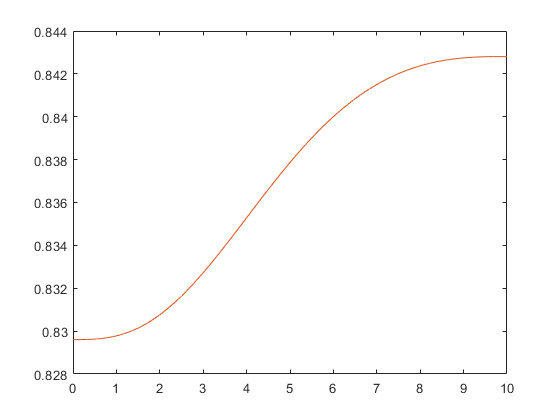

tt_All2 = etime(tt_4,tt_6);
% 求解关节角速度
theta2_Orientation = confi_opti2.' * pi / 180;       % 定义机械臂初始构型    % ini_confi*pi/180      % 单位转化，将°转化为rad
angle2_alljoint = zeros(7,nn);      % 记录各关节角的中间变量，用于绘制角度变化曲线
vel2_theta = zeros(7,nn);         % 各关节角速度，用于绘制角速度变化曲线
v2_allend = zeros(6,nn);          % 根据得到的角速度计算末端速度，用于验证误差
ang2_dedai = zeros(7,nn);         % 记录每个采样周期内的角度变化量
angle2_alljoint(:,1) = theta2_Orientation;          

for ii=1 : nn
    Theta_update = angle2_alljoint(:,ii);
    matrix_jacobi = JoiAngToJacMatBase(Theta_update);
    matrix_zhuanzhi = matrix_jacobi.';
    matrix_ladder = matrix_jacobi * matrix_zhuanzhi;      % inv(matrix_jacobi*matrix_zhuanzhi);
    jacobi_inv = matrix_zhuanzhi / matrix_ladder;
    v_joint = jacobi_inv * v_zposi(:,ii);      %计算关节速度v_joint
    vel2_theta(:,ii) = v_joint;                  % 记录关节角速度，绘制图像
    v2_allend(:,ii) = matrix_jacobi * v_joint;    % 根据求出的关节速度计算末端速度进行验证
    
    ang2_dedai(:,ii) = vel_theta(:,ii) * t_int;      % 每个采样周期内的角度变化量
    angle2_alljoint(:,ii+1) = angle2_alljoint(:,ii) + ang2_dedai(:,ii);
end
% 绘制关节角度和角速度变化曲线
angle2_alljoint(:,nn+1) = [];         % 去除关节角度中多余的一列
% JoiAng_deg = angle_alljoint*180/pi;
Mani22_confiopti = zeros(nn,1);
norm22_maniconfi = zeros(nn,1);
for ii= 1:nn
%     Theta_degree = conf_opti(ii,:);
    Theta_rad = angle2_alljoint(:,ii);            % Theta_degree * pi / 180;
    Jaco_Base = JoiAngToJacMatBase(Theta_rad);
    Trans_JacoBase = Jaco_Base.';
    det_JacoBase = det(Jaco_Base * Trans_JacoBase);
    Mani22_confiopti(ii) = sqrt(det_JacoBase);
    norm22_maniconfi(ii) = Mani22_confiopti(ii) / 30;       % 可操作度归一化
end
% 绘制从所有逆解和优化逆解中得到的操作构型的可操作度变化
plot(t_sam,norm11_maniconfi);
hold on;
plot(t_sam,norm22_maniconfi);
hold off;

%% 程序所需函数

function angle = WeiziToJointAngle(PostureMatrix)
%% 求解末端位姿已知时，在关节角2运动范围内，固定关节角2时的所有构型
% 假设当前构型为currentJntAng = [pi/4 pi/4 pi/4 pi/4 pi/4 pi/4 pi/4]
%%
currentJntAng = [pi/4 pi/4 pi/4 pi/4 pi/4 pi/4 pi/4];   %此处可以直接用给定的关节角
theta2min = -270.0; theta2max = 270.0;
kk = 1;
for ii=theta2min:0.5:theta2max
    
    theta2 = ii*pi/180;
    JointAng = InverseKinematicsSpecifiedJoint2(theta2,PostureMatrix,currentJntAng);
    angle(kk,:) = JointAng;  %得到所有关节角用于后续剔除与给定末端位姿不一样的构型
    all_angle(kk,:) = JointAng;  %得到所有关节角用于对比
    kk = kk+1;
end
aa = size(angle,1);
for bb = 1:aa
    matrix_angle = xbForKinEnd(angle(bb,:));
    for cc = 1:3
        for dd = 1:4
            if abs(matrix_angle(cc,dd) - PostureMatrix(cc,dd)) >= 1e-3     % 因为两个构型的末端姿态不一致，所以应该是大于等于
                angle(bb,:) = zeros(1,7);    %构型不一致的关节角统一为0
            end
        end
    end
end
ee = 1;
matrix_error_number = [];
for ff = 1:aa
    if angle(ff,:) == 0  %记录关节角为0时，对应关节2的角度
        matrix_error_number(ee) = ff;
        ee = ee+1;
    end
end
gg = isempty(matrix_error_number);
if gg == 0
 angle(matrix_error_number,:) = []; %剔除末端位姿不一致的所在行
end
% angle_degree = angle * 180 /pi;
end

function JointAng = InverseKinematicsSpecifiedJoint2(theta2,Pos_Orien,CurrentJntAng )
%*************************************************************/
%	函数名称:		InverseKinematicsSpecifiedJoint2
% 	函数功能:		求解指定关节2的逆运动学
% 	参数:			theta2: 固定关节的角度，单位--弧度
% 				  Pos_Orien[4][4]：末端EE相对基座标{0}的变换矩阵(参见文档“初样实验舱机械臂DH参数.doc”)
% 				  currentJntAng[7]:当前关节角，单位--弧度
% 	返回值:
% 				  JointAng[7]：输出变量，逆运动学计算的关节角，单位--弧度
%   JointAng = InverseKinematicsSpecifiedJoint2(21*pi/180,T0e,currentJntAng)
%*************************************************************/

a0 = 0.7161;
a1 = 0.430;
a2 = 0.430;
a3 = 2.080;
a4 = 0.387;
a5 = 2.080;
a6 = 0.430;
a7 = 0.430;
a8 = 0.7161;

thetaLimit = 270.0*pi/180.0;% range
% format short
nx=Pos_Orien(1,1);  %末端对基坐标系的转换矩阵
ny=Pos_Orien(2,1);
nz=Pos_Orien(3,1);
sx=Pos_Orien(1,2);
sy=Pos_Orien(2,2);
sz=Pos_Orien(3,2);
ax=Pos_Orien(1,3);
ay=Pos_Orien(2,3);
az=Pos_Orien(3,3);
px=Pos_Orien(1,4);
py=Pos_Orien(2,4);
pz=Pos_Orien(3,4);

InverseSolution = CurrentJntAng;    %当前随机定义的一组关节角
num = 0;
%%
% if theta2 > thetaLimit
%     theta2 = theta2 - floor(theta2/(2*pi))*2*pi;      %将超出运动上限的关节角调整至[-2pi, 2pi]范围内
% elseif theta2 < -thetaLimit
%     theta2 = theta2 + floor(theta2/(2*pi))*2*pi;
% end
s2 = sin(theta2);
c2 = cos(theta2);
a = pz - a8*nz;
b = a8*ny - py;
c = ((a8*nx - px - a0)*c2 - (a2 + a4 + a6))/s2;
phai = atan2(b,a);
Sin_xita = c/sqrt(a^2 + b^2);

if (1 - Sin_xita^2)<0
    temp = 0;
     disp('关节2角度不合适');
else
    temp = sqrt(1 - Sin_xita^2);
end

Cos_xita_1 = temp;
Cos_xita_2 = -Cos_xita_1;
xita_1 = atan2(Sin_xita,Cos_xita_1);
xita_2 = atan2(Sin_xita,Cos_xita_2);
theta1_possible1 = xita_1 - phai;
theta1_possible2 = xita_2 - phai;
theta1_possible=[theta1_possible1,theta1_possible2];

for i=1:2
    theta1 = theta1_possible(i);
    s1 = sin(theta1);
    c1 = cos(theta1);
    Cos_theta6 = (ny*c1 - nz*s1)*s2 - nx*c2;
    
    if (1 - Cos_theta6^2) < 0
        %                 temp = 0;
        disp('关节6奇异');
        continue;
        %                 
    else
        temp = sqrt(1 - Cos_theta6^2);
    end
    
    Sin_theta6_possible1 = temp;
    Sin_theta6_possible2 = -Sin_theta6_possible1;
    theta6_possible1 = atan2(Sin_theta6_possible1,Cos_theta6);
    theta6_possible2 = atan2(Sin_theta6_possible2,Cos_theta6);
    theta6_possible=[theta6_possible1,theta6_possible2];
    
    for j=1:2
        theta6 = theta6_possible(j);
        s6 = sin(theta6);
        %           c6 = cos(theta6);
        
        if abs(s6) > 1e-5
            theta7 = atan2(((ay*c1 - az*s1)*s2 - ax*c2)/s6,(sx*c2 - (sy*c1 - sz*s1)*s2)/s6);
        else
            %               disp('奇异构型3457四轴平行');
            theta7 = CurrentJntAng(7);
        end
        
        s7 = sin(theta7);
        c7 = cos(theta7);
        
        A = s2*(-a0 + a8*nx - px + a7*ax*c7 + a7*sx*s7) + c1*c2*(a8*ny - py + a7*ay*c7 + a7*sy*s7) - c2*s1*(a8*nz - pz + a7*az*c7 + a7*sz*s7);
        B = -a1 + s1*(a8*ny - py + a7*ay*c7 + a7*sy*s7) +  c1*(a8*nz - pz + a7*az*c7 + a7*sz*s7);
        Cos_theta4 = (A^2 + B^2 - a3^2 -a5^2)/(2*a3*a5);
        
        if (1 - Cos_theta4^2) < 0
            %                 temp = 0;
            disp('关节2轴线交于末端，构型奇异');
            continue;
        else
            temp = sqrt(1 - Cos_theta4^2);
        end
        
        Sin_theta4_possible1 = temp;
        Sin_theta4_possible2 = -Sin_theta4_possible1;
        theta4_possible1 = atan2(Sin_theta4_possible1,Cos_theta4);
        theta4_possible2 = atan2(Sin_theta4_possible2,Cos_theta4);
        theta4_possible=[theta4_possible1,theta4_possible2];
        
        for k=1:2
            theta4 = theta4_possible(k);
            s4 = sin(theta4);
            c4 = cos(theta4);
            s3 = (A*(a3 + a5*c4) - B*a5*s4)/(a3^2 + a5^2 + 2*a3*a5*c4);
            c3 = (B*(a3+a5*c4) + A*a5*s4)/(a3^2 + a5^2 + 2*a3*a5*c4);
            theta3 = atan2(s3,c3);
            
            s345 = -s2*(ax*c7 + sx*s7) - c1*c2*(ay*c7 + sy*s7) + s1*c2*(az*c7 + sz*s7);
            c345 = -s1*(ay*c7 + sy*s7) - c1*(az*c7 + sz*s7);
            s34 = (A - a3*s3)/a5;
            c34 = (B - a3*c3)/a5;
            theta5 = atan2(s345*c34 - c345*s34 , s34*s345 + c34*c345);
            
            num = num + 1;
            %           InverseSolution(num,:) = [theta1,theta3,theta4,theta5,theta6,theta7];%不包含关节2
            InverseSolution(num,:) = [theta1,theta2,theta3,theta4,theta5,theta6,theta7];
%             AllSolution(num,:) = [theta1,theta2,theta3,theta4,theta5,theta6,theta7];
        end
    end
end
%% 将逆解运动范围调整到±270（atan2的求解为±180）,增加为新的逆解

InverseSolution_revise = InverseSolution(:,[1,3:7]);
addone = 0;
for i=1:num*2^6 %解的最多个数，除去关节2，每组对应最多2^6组合?
    for j=1:6 %每组解的关节个数
        if InverseSolution_revise(i,j) + 2*pi < thetaLimit
            InverseSolution_add = zeros(1,6);
            for k = 1:6
                if k == j
                    InverseSolution_add(k) = InverseSolution_revise(i,k) + 2*pi;
                else
                    InverseSolution_add(k) = InverseSolution_revise(i,k);
                end
            end
            addone = addone + 1;
            InverseSolution_revise(num + addone,:) = InverseSolution_add;
            
        elseif InverseSolution_revise(i,j) - 2*pi > -thetaLimit
            InverseSolution_add = zeros(1,6);
            for k = 1:6
                if k == j
                    InverseSolution_add(k) = InverseSolution_revise(i,k) - 2*pi;
                else
                    InverseSolution_add(k) = InverseSolution_revise(i,k);
                end
            end
            addone = addone + 1;
            InverseSolution_revise(num + addone,:) = InverseSolution_add;
        end
    end
end

% InverseSolution_revise_8 = roundn(InverseSolution_revise,-8);%去重的运算精度。小数点后8位
InverseSolution_optional = unique(InverseSolution_revise,'rows');%去除重复行

weight =3000*diag([1,0.8,0.5,0.4,0.3,0.2]);%基关节权重大，使能量最小
num_solution = size(InverseSolution_optional,1);    %求矩阵行数
dist=zeros(1,num_solution);
for i=1:num_solution
%     dist(i) = norm([CurrentJntAng(1),CurrentJntAng(3:7)]-InverseSolution_optional(i,:));
dist(i) = ([CurrentJntAng(1),CurrentJntAng(3:7)]-InverseSolution_optional(i,:))*weight*([CurrentJntAng(1),CurrentJntAng(3:7)]-InverseSolution_optional(i,:))';
%     JointAng(i,:) = [InverseSolution_optional(i,1),theta2,InverseSolution_optional(i,2:6)];
end
[~ , min_number]= min(dist);
JointAng = [InverseSolution_optional(min_number,1),theta2,InverseSolution_optional(min_number,2:6)];
end

function [Tend_end] = xbForKinEnd(Theta)
%% 建立以末端坐标系为参考的小臂正运动学求解方程；
% Theta为包含七个关节角度的数组，单位是rad；
% 求解Tend_1的关节螺旋轴和点的位置均为相对末端坐标系得到；
% 输出结果Tend_end为各关节旋转任意角度后的末端坐标系相对基坐标系的位姿矩阵；
%% 用于单位转化，不能同时运行
% Theta_deg = Theta_deg * 180 / pi;
Theta_deg = Theta;
%% 
a0N = 0.7161;
a1N = 0.430;
a2N = 0.430;
a3N = 2.080;
a4N = 0.387;
a5N = 2.080;
a6N = 0.430;
a7N = 0.430;
a8N = 0.7161;

theta1 = Theta_deg(1);
theta2 = Theta_deg(2);
theta3 = Theta_deg(3);
theta4 = Theta_deg(4);
theta5 = Theta_deg(5);
theta6 = Theta_deg(6);
theta7 = Theta_deg(7);

M_ori = [-1     0   0   -a0N-a2N-a4N-a6N-a8N;
         0      1   0   0;
         0      0   -1  -a1N-a3N-a5N-a7N;
         0      0   0   1];
Tend_1 = [1     0               0               0;
          0     cos(theta1)    -sin(theta1)   -(a1N + a3N + a5N + a7N)*sin(theta1);
          0     sin(theta1)    cos(theta1)    (cos(theta1) - 1)*(a1N + a3N + a5N + a7N);
          0     0               0               1];
Tend_2 = [cos(theta2)       -sin(theta2)    0   (cos(theta2) - 1)*(a2N + a4N + a6N + a8N);
          sin(theta2)       cos(theta2)     0   sin(theta2)*(a2N + a4N + a6N + a8N);
          0                 0               1   0;
          0                 0               0   1];
Tend_3 = [1     0               0               0;
          0     cos(theta3)     -sin(theta3)    -sin(theta3)*(a3N + a5N + a7N);
          0     sin(theta3)     cos(theta3)     (cos(theta3) - 1)*(a3N + a5N + a7N);
          0     0               0               1];
Tend_4 = [1     0               0               0;
          0     cos(theta4)     -sin(theta4)    -sin(theta4)*(a5N + a7N);
          0     sin(theta4)     cos(theta4)     (a5N + a7N)*(cos(theta4) - 1);
          0     0               0               1];
Tend_5 = [1     0               0               0;
          0     cos(theta5)     -sin(theta5)    -a7N*sin(theta5);
          0     sin(theta5)     cos(theta5)     a7N*(cos(theta5) - 1);
          0     0               0               1];
Tend_6 = [cos(theta6)       -sin(theta6)        0   a8N*(cos(theta6) - 1);
          sin(theta6)       cos(theta6)         0   a8N*sin(theta6);
          0                 0                   1   0;
          0                 0                   0   1];
Tend_7 = [1     0               0               0;
          0     cos(theta7)     -sin(theta7)    0;
          0     sin(theta7)     cos(theta7)     0;
          0     0               0               1];

Tend_end = M_ori * Tend_1 * Tend_2 * Tend_3 * Tend_4 * Tend_5 * Tend_6 * Tend_7;
end

function [Confi_var] = ConVelToAngVar(con_ini,v_end)
%% 根据给定的初始构型和末端速度，计算构型调整量
%   输出量为构型调整量
%%
m = size(v_end,2);       % size(v_end,2);
t_int = 0.002;  % 采样间隔

theta1_ladder = zeros(1,m);     % 各关节角度
theta2_ladder = zeros(1,m);
theta3_ladder = zeros(1,m);
theta4_ladder = zeros(1,m);
theta5_ladder = zeros(1,m);
theta6_ladder = zeros(1,m);
theta7_ladder = zeros(1,m);
v_theta1 = zeros(1,m);      % 各关节角速度
v_theta2 = zeros(1,m);
v_theta3 = zeros(1,m);
v_theta4 = zeros(1,m);
v_theta5 = zeros(1,m);
v_theta6 = zeros(1,m);
v_theta7 = zeros(1,m);
% v_allend = zeros(6,m);
ang_dedai1 = zeros(1,m);
ang_dedai2 = zeros(1,m);
ang_dedai3 = zeros(1,m);
ang_dedai4 = zeros(1,m);
ang_dedai5 = zeros(1,m);
ang_dedai6 = zeros(1,m);
ang_dedai7 = zeros(1,m);

theta_Orientation = con_ini * pi / 180;      % 关节角度单位转化，将°转化为rad

theta1_ladder(1) = theta_Orientation(1);
theta2_ladder(1) = theta_Orientation(2);
theta3_ladder(1) = theta_Orientation(3);
theta4_ladder(1) = theta_Orientation(4);
theta5_ladder(1) = theta_Orientation(5);
theta6_ladder(1) = theta_Orientation(6);
theta7_ladder(1) = theta_Orientation(7);

for ii=1:m
    Theta_update = [theta1_ladder(ii) theta2_ladder(ii) theta3_ladder(ii) theta4_ladder(ii) theta5_ladder(ii) theta6_ladder(ii) theta7_ladder(ii)];
    matrix_jacobi = JoiAngToJacMatBase(Theta_update);
    matrix_zhuanzhi = matrix_jacobi.';
    matrix_ladder = matrix_jacobi*matrix_zhuanzhi;      % inv(matrix_jacobi*matrix_zhuanzhi);
    jacobi_inv = matrix_zhuanzhi / matrix_ladder;
    v_joint = jacobi_inv * v_end(:,ii);      %计算关节速度v_joint
    v_theta1(ii) = v_joint(1);
    v_theta2(ii) = v_joint(2);
    v_theta3(ii) = v_joint(3);
    v_theta4(ii) = v_joint(4);
    v_theta5(ii) = v_joint(5);
    v_theta6(ii) = v_joint(6);
    v_theta7(ii) = v_joint(7);
%     v_allend(:,ii) = matrix_jacobi * v_joint;    % 根据求出的关节速度计算末端速度进行验证
    ang_dedai1(ii) = v_theta1(ii)*t_int;
    ang_dedai2(ii) = v_theta2(ii)*t_int;
    ang_dedai3(ii) = v_theta3(ii)*t_int;
    ang_dedai4(ii) = v_theta4(ii)*t_int;
    ang_dedai5(ii) = v_theta5(ii)*t_int;
    ang_dedai6(ii) = v_theta6(ii)*t_int;
    ang_dedai7(ii) = v_theta7(ii)*t_int;

    theta1_ladder(ii+1) = theta1_ladder(ii) + ang_dedai1(ii);
    theta2_ladder(ii+1) = theta2_ladder(ii) + ang_dedai2(ii);
    theta3_ladder(ii+1) = theta3_ladder(ii) + ang_dedai3(ii);
    theta4_ladder(ii+1) = theta4_ladder(ii) + ang_dedai4(ii);
    theta5_ladder(ii+1) = theta5_ladder(ii) + ang_dedai5(ii);
    theta6_ladder(ii+1) = theta6_ladder(ii) + ang_dedai6(ii);
    theta7_ladder(ii+1) = theta7_ladder(ii) + ang_dedai7(ii);
end
% v_alljoint = [v_theta1;v_theta2;v_theta3;v_theta4;v_theta5;v_theta6;v_theta7];
% 去除关节角度中多余的一列
theta1_ladder(m+1)=[];
theta2_ladder(m+1)=[];
theta3_ladder(m+1)=[];
theta4_ladder(m+1)=[];
theta5_ladder(m+1)=[];
theta6_ladder(m+1)=[];
theta7_ladder(m+1)=[];
angle_alljoint = [theta1_ladder; theta2_ladder; theta3_ladder; theta4_ladder; theta5_ladder; theta6_ladder; theta7_ladder];

con_fin = angle_alljoint(:,5001);
confin_deg = con_fin * 180 /pi;
zhuanzhi_conini = con_ini.';
deta_con = abs(confin_deg - zhuanzhi_conini);     % abs(confin_deg - zhuanzhi_conini);
wei_joi = [1.4 1.4 1.4 1.05 0.7 0.7 0.35];
Confi_var = wei_joi * deta_con;
end

function [Jaco_base] = JoiAngToJacMatBase(Theta_rad)
%% 计算以基坐标系为参考的雅可比矩阵
%   输入量为包含7个关节角度的数组，单位为弧度rad；
%   输出量为使用旋量法以基坐标系为参考的雅可比矩阵
%% 机械臂关节常量定义
a0N = 0.7161;
a1N = 0.430;
a2N = 0.430;
a3N = 2.080;
a4N = 0.387;
a5N = 2.080;
a6N = 0.430;
a7N = 0.430;
a8N = 0.7161;

%% 关节角度赋值
theta1 = Theta_rad(1);
theta2 = Theta_rad(2);
theta3 = Theta_rad(3);
theta4 = Theta_rad(4);
theta5 = Theta_rad(5);
theta6 = Theta_rad(6);
theta7 = Theta_rad(7);
%% 求解公式
JB_S1 = [-1;
          0;
          0;
          0;
          0;
          0];
JB_S2 = [0;
         -sin(theta1);
         -cos(theta1);
         0;
         -a0N*cos(theta1);
         a0N*sin(theta1)];
JB_S3 = [-cos(theta2);
         cos(theta1)*sin(theta2);
         -sin(theta1)*sin(theta2);
         a1N*sin(theta2);
         a1N*cos(theta1)*cos(theta2) - a0N*cos(theta2)*sin(theta1)*sin(theta2) + a0N*sin(theta1)*sin(theta2)*(cos(theta2) - 1);
         a0N*cos(theta1)*sin(theta2)*(cos(theta2) - 1) - a0N*cos(theta1)*cos(theta2)*sin(theta2) - a1N*cos(theta2)*sin(theta1)];
JB_S4 = [-cos(theta2);
         cos(theta1)*sin(theta2);
         -sin(theta1)*sin(theta2);
         cos(theta3)*sin(theta2)*(a1N + a3N) - cos(theta1)*sin(theta2)*(a0N*sin(theta1)*sin(theta2) + a1N*cos(theta1)*(cos(theta3) - 1) - a1N*cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta1)*sin(theta2)*(a1N*sin(theta1)*(cos(theta3) - 1) - a0N*cos(theta1)*sin(theta2) + a1N*cos(theta1)*cos(theta2)*sin(theta3));
         sin(theta1)*sin(theta2)*(a0N*(cos(theta2) - 1) + a1N*sin(theta2)*sin(theta3)) - (a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) - cos(theta2)*(a0N*sin(theta1)*sin(theta2) + a1N*cos(theta1)*(cos(theta3) - 1) - a1N*cos(theta2)*sin(theta1)*sin(theta3));
         cos(theta2)*(a1N*sin(theta1)*(cos(theta3) - 1) - a0N*cos(theta1)*sin(theta2) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) - (a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + cos(theta1)*sin(theta2)*(a0N*(cos(theta2) - 1) + a1N*sin(theta2)*sin(theta3))];
JB_S5 = [-cos(theta2);
         cos(theta1)*sin(theta2);
         -sin(theta1)*sin(theta2);
         - (sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2))*(a1N + a3N + a5N) - cos(theta1)*sin(theta2)*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) - a1N*cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta1)*sin(theta2)*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + a1N*cos(theta1)*cos(theta2)*sin(theta3));
         sin(theta1)*sin(theta2)*(a0N*(cos(theta2) - 1) + a1N*sin(theta2)*sin(theta3) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1)) - (cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)))*(a1N + a3N + a5N) - cos(theta2)*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) - a1N*cos(theta2)*sin(theta1)*sin(theta3));
         cos(theta2)*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) - (cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)))*(a1N + a3N + a5N) + cos(theta1)*sin(theta2)*(a0N*(cos(theta2) - 1) + a1N*sin(theta2)*sin(theta3) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1))];
JB_S6 = [sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) - cos(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3));
         sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) - cos(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)));
         sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) - cos(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)));
         (cos(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)))*(a1N + a3N + a5N) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))*(a1N + a3N + a5N) - a1N*cos(theta2)*sin(theta1)*sin(theta3)) - (cos(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1))) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)))*(a1N + a3N + a5N) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))*(a1N + a3N + a5N) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) + (cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)))*(a0N + a2N + a4N + a6N);
         (cos(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1))) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))))*(a0N*(cos(theta2) - 1) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2))*(a1N + a3N + a5N) + (cos(theta5) - 1)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))*(a1N + a3N + a5N) + a1N*sin(theta2)*sin(theta3) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1)) + (cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))))*(a0N + a2N + a4N + a6N) - (cos(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)))*(a1N + a3N + a5N) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))*(a1N + a3N + a5N) - a1N*cos(theta2)*sin(theta1)*sin(theta3));
         (cos(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)))*(a1N + a3N + a5N) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))*(a1N + a3N + a5N) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) - (cos(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))))*(a0N*(cos(theta2) - 1) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2))*(a1N + a3N + a5N) + (cos(theta5) - 1)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))*(a1N + a3N + a5N) + a1N*sin(theta2)*sin(theta3) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1)) + (cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1))))*(a0N + a2N + a4N + a6N)];
JB_S7 = [- cos(theta2)*cos(theta6) - sin(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)));
         cos(theta1)*cos(theta6)*sin(theta2) - sin(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))));
         - sin(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))) - cos(theta6)*sin(theta1)*sin(theta2);
         (cos(theta2)*sin(theta6) - cos(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))))*(a1N + a3N + a5N + a7N) - (sin(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))) + cos(theta6)*sin(theta1)*sin(theta2))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)))*(a1N + a3N + a5N) + sin(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))))*(a0N + a2N + a4N + a6N) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))*(a1N + a3N + a5N) - cos(theta1)*sin(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) + (sin(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))) - cos(theta1)*cos(theta6)*sin(theta2))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)))*(a1N + a3N + a5N) + sin(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1))))*(a0N + a2N + a4N + a6N) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))*(a1N + a3N + a5N) + sin(theta1)*sin(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) - a1N*cos(theta2)*sin(theta1)*sin(theta3));
         (sin(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))) + cos(theta6)*sin(theta1)*sin(theta2))*(a0N*(cos(theta2) - 1) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2))*(a1N + a3N + a5N) + cos(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) + (cos(theta5) - 1)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))*(a1N + a3N + a5N) + a1N*sin(theta2)*sin(theta3) + sin(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)))*(a0N + a2N + a4N + a6N) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1)) - (cos(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))) + cos(theta1)*sin(theta2)*sin(theta6))*(a1N + a3N + a5N + a7N) - (cos(theta2)*cos(theta6) + sin(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) + a0N*sin(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)))*(a1N + a3N + a5N) + sin(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1))))*(a0N + a2N + a4N + a6N) + a1N*cos(theta1)*(cos(theta3) - 1) - sin(theta4)*(a1N + a3N)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))*(a1N + a3N + a5N) + sin(theta1)*sin(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) - a1N*cos(theta2)*sin(theta1)*sin(theta3));
         (cos(theta2)*cos(theta6) + sin(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))))*((a1N + a3N)*(cos(theta4) - 1)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - a0N*cos(theta1)*sin(theta2) - sin(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)))*(a1N + a3N + a5N) + sin(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3))))*(a0N + a2N + a4N + a6N) - sin(theta4)*(a1N + a3N)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + a1N*sin(theta1)*(cos(theta3) - 1) + (cos(theta5) - 1)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))*(a1N + a3N + a5N) - cos(theta1)*sin(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) + a1N*cos(theta1)*cos(theta2)*sin(theta3)) - (cos(theta6)*(cos(theta5)*(cos(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)) + sin(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta1)*cos(theta3) - cos(theta2)*sin(theta1)*sin(theta3)) - sin(theta4)*(cos(theta1)*sin(theta3) + cos(theta2)*cos(theta3)*sin(theta1)))) - sin(theta1)*sin(theta2)*sin(theta6))*(a1N + a3N + a5N + a7N) - (sin(theta6)*(cos(theta5)*(cos(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)) + sin(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3))) + sin(theta5)*(cos(theta4)*(cos(theta3)*sin(theta1) + cos(theta1)*cos(theta2)*sin(theta3)) - sin(theta4)*(sin(theta1)*sin(theta3) - cos(theta1)*cos(theta2)*cos(theta3)))) - cos(theta1)*cos(theta6)*sin(theta2))*(a0N*(cos(theta2) - 1) - sin(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2))*(a1N + a3N + a5N) + cos(theta2)*(cos(theta6) - 1)*(a0N + a2N + a4N + a6N) + (cos(theta5) - 1)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3))*(a1N + a3N + a5N) + a1N*sin(theta2)*sin(theta3) + sin(theta6)*(cos(theta5)*(sin(theta2)*sin(theta3)*sin(theta4) - cos(theta3)*cos(theta4)*sin(theta2)) + sin(theta5)*(cos(theta3)*sin(theta2)*sin(theta4) + cos(theta4)*sin(theta2)*sin(theta3)))*(a0N + a2N + a4N + a6N) + cos(theta3)*sin(theta2)*sin(theta4)*(a1N + a3N) + sin(theta2)*sin(theta3)*(a1N + a3N)*(cos(theta4) - 1))];
Jaco_lad = [JB_S1  JB_S2  JB_S3   JB_S4   JB_S5   JB_S6   JB_S7];
Jaco_base = [Jaco_lad(4:6,:);Jaco_lad(1:3,:)];
end
